# Automatic Control Project

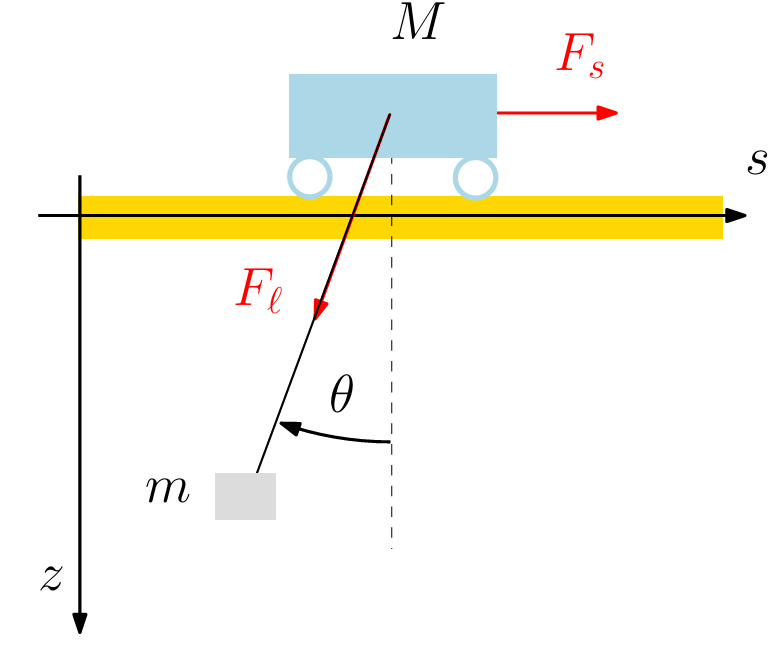

clear
clc
syms t M m c g l0 l(t) s0 s(t) theta(t) ds dl dtheta
% M  - Mass troley [kg]
% m  - Mass load [kg]
% c  - Damping coefitient [Ns/m]
% g  - Gravity accel [m/s^2]
% l0 - Nominal rope length [m]
% l  - Rope length [m]
% s0 - Nominal troley position [m]
% s  - Troley position [m]
% θ  - Swing angle [rad]

syms Fs Fl y_x y_y
% Fs - Force troley alongside bridge [N]
% Fl - Force pulling the rope [N]


#### System

x = [s-s0; l-l0; theta; ds; dl; dtheta];
dx = diff(x,t);
u = [Fs;Fl-m*g];

A = [0 0 0 1 0 0
     0 0 0 0 1 0
     0 0 0 0 0 1
     0 0 -g*m/M -c/M 0 0
     0 0 0 0 0 0
     0 0 -g*(M+m)/(M*l0) -c/(M*l0) 0 0];

B = [
    0 0 0 1/M 0 1/(M*l0)
    0 0 0  0 1/m 0].';

C = sym([1 0 0 0 0 0
     0 1 0 0 0 0]);

D = sym([0 0
     0 0]);

dynamic_system1 = dx == A*x + B*u;
dynamic_system2 = [y_x; y_y] == C*x + D*u;

# Question 1

#### Controllability

R = [B A*B A^2*B A^3*B A^4*B A^5*B];
rank(R) == size(A,1)

ans = logical
   1


#### Observability

O= [ C; C*A; C*A^2; C*A^3; C*A^4; C*A^5];
rank(O) == size(A,1)

ans = logical
   1


# Question 2

#### Observer Design (L)

Here we compute the observer gain L using LMIs to ensure fast estimation convergence.

Solving the dual LMI: (Aᵀ·W - Cᵀ·Y) + (Aᵀ·W - Cᵀ·Y)ᵀ ≤ -2α·W, with L = W⁻¹·Yᵀ. Ensures that the eigenvalues of (A - L·C) have real parts < -α.

% Observer Design
vM = 2000;
vm = 10000;
vc = 300;
vg = 9.81;
vs0 = 2;
vl0 = 1;
vals = [vM; vm; vc; vg; vs0; vl0];

A_num = double(subs(A, [M; m; c; g; s0; l0], vals));
C_num = double(C);
B_num = double(subs(B, [M; m; c; g; s0; l0], vals));

% Convergence rate
alpha = 6;

% Number of States, Inputs and Outputs
n = 6;
m = 2;
p = 2;

% YALMIP settings
yalmip('clear');
opts = sdpsettings('solver', 'mosek', 'verbose', 0);
fake_zero = 1e-4;

W_obs = sdpvar(n,n);
Y = sdpvar(p,n);

constr_L = [W_obs >= fake_zero*eye(n);
            (A_num'*W_obs - C_num'*Y) + (A_num'*W_obs - C_num'*Y)' <= -2*alpha*W_obs];


sol_L = solvesdp(constr_L, [], opts);
[primal_res_L, dual_res_L] = check(constr_L);

State Feedback Observer fesability

all([primal_res_L; dual_res_L] >= -fake_zero)

ans = logical
   1


Wv_obs = value(W_obs);
Yv = value(Y);
L = inv(Wv_obs) * Yv';
Gain_L = mat2str(L, 4)

Gain_L = '[50.83 1.597e-14;-3.569e-14 19.31;-202 -7.885e-14;1181 3.812e-13;-3.003e-13 159.2;288.1 -2.214e-14]'

Observer_poles = mat2str(real(eig(A_num - L*C_num)), 4) %(A - L*C)

Observer_poles = '[-17.23;-17.23;-8.256;-8.256;-9.655;-9.655]'

# Question 3

#### Objective

For each desired convergence rate alpha_i = i (i = 1,2,3), compute a feedback gain K_i minimizing ||K_i||, while ensuring that the closed-loop system (A + B*K_i) is stable with R(eig) < -alpha_i. we return their gain norms and their upper bound, we also display the closed loop system eig.

% Solve LMI with YALMIP

K_list = {}; P_list = {}; mu_list = []; eig_list = [];

for alpha_i = 1:3
    yalmip('clear');
    W = sdpvar(n,n);
    X = sdpvar(m,n);
    mu = sdpvar(1,1);

    % LMI formulation
    LMI_K = [
        W >= fake_zero*eye(n),
        (A_num*W + B_num*X) + (A_num*W + B_num*X)' <= -2*alpha_i*W,
        [mu*eye(n), X'; X, mu*eye(m)] >= fake_zero*eye(n+m)
    ];

    diagnostics = optimize(LMI_K, mu, opts);
    fprintf("- Feedback gain K_%d. Convergence rate α = %d\n", alpha_i, alpha_i);
    
    Wv = value(W); Xv = value(X);
    K_i = Xv * inv(Wv);
    mu_i = value(mu);
    eigs_cl = real(eig(A_num + B_num*K_i));
    
    % Store
    K_list{alpha_i} = K_i;
    mu_list(alpha_i) = mu_i;
    eig_list{alpha_i} = eigs_cl;
    P_list{alpha_i} = inv(Wv);
    
    fprintf("Gain matrix K_%d:\n%s\n", alpha_i, mat2str(K_i,4));
    fprintf("Eigenvalues of A + BK_%d:\n%s\n", alpha_i, mat2str(eigs_cl,4));
    fprintf("Upper bound mu: %.4f\n", mu_i);
    fprintf("||K_%d|| = %.4f\n", alpha_i, norm(K_i));
end

- Feedback gain K_1. Convergence rate α = 1


Gain matrix K_1:
[-1.809e+04 5.308e-16 4.735e+04 -1.61e+04 2.006e-17 8405;-2.07e-15 -4.218e+04 -9.426e-14 -1.008e-14 -3.547e+04 1.622e-14]


Eigenvalues of A + BK_1:
[-1;-1;-1;-1;-1.774;-1.774]


Upper bound mu: 39.0638


||K_1|| = 55117.3464


- Feedback gain K_2. Convergence rate α = 2


Gain matrix K_2:
[-8.684e+04 -1.311e-11 1.563e+04 -6.369e+04 -5.388e-12 4.799e+04;1.747e-10 -1.863e+05 5.37e-11 1.085e-10 -7.437e+04 -1.072e-10]


Eigenvalues of A + BK_2:
[-2;-2;-2;-2;-3.719;-3.719]


Upper bound mu: 335.5452


||K_2|| = 200642.4917


- Feedback gain K_3. Convergence rate α = 3


Gain matrix K_3:
[-2.42e+05 -7.701e-11 6.472e+04 -1.361e+05 -2.008e-11 1.124e+05;1.078e-09 -4.161e+05 -3.915e-10 4.779e-10 -1.059e+05 -4.641e-10]


Eigenvalues of A + BK_3:
[-3;-3;-3;-3;-5.295;-5.295]


Upper bound mu: 2608.8964


||K_3|| = 429371.0963


We compare their performance in simulation of both linear and nonlinear systems.

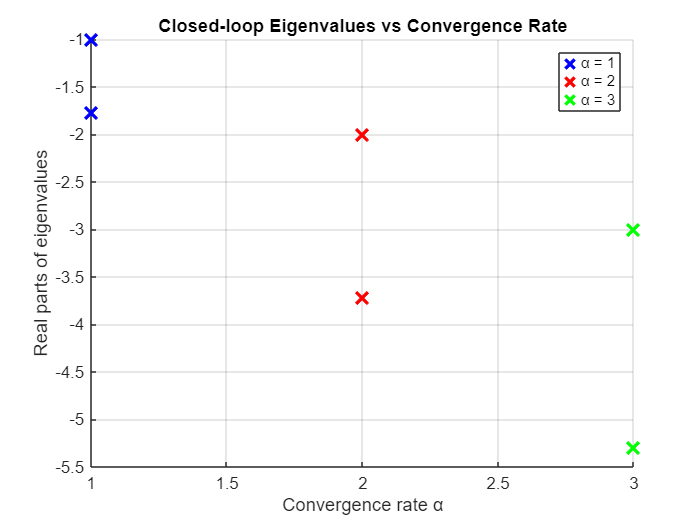

figure; hold on; grid on;
colors = {'b', 'r', 'g'};
for i = 1:3
    plot(i * ones(size(eig_list{i})), eig_list{i}, 'x', 'Color', colors{i}, 'MarkerSize', 10, 'LineWidth', 2)
end
xlabel('Convergence rate α'); ylabel('Real parts of eigenvalues');
title('Closed-loop Eigenvalues vs Convergence Rate');
legend('α = 1','α = 2','α = 3');

#### State Trajectories

We now compare the three simulations both for the real state and the observer.

% Initial conditions
x_eq = [vs0; vl0; 0; 0; 0; 0];
x0 = [0.2; 0.2; -pi/20; 0; 0; 0];   % True initial state
xhat0 =  [0.2; 0.2; 0; 0; 0; 0]; % Initial observer estimate
x_aug0 = [x0; xhat0];

% Set the time span for the simulation
t_span = [0 5];

% Simulation for each controller
results = {};
for i = 1:length(K_list)
    fprintf('Simulating with controller K_%d (α = %d)...\n', i, i);
    K = K_list{i};
    f = @(t, x_aug) observer_augmented_ode(t, x_aug, A_num, B_num, C_num, K, L); 
    % Run simulation
    [t, X_aug] = ode45(f, t_span, x_aug0);
    
    results{i}.t = t;
    results{i}.x_lin = X_aug(:, 1:6);
    Xhat = X_aug(:, 7:12);  % estimated state
    results{i}.x_lin_estimated=Xhat;
    U = (K * Xhat')';  % each row is u = K*xhat
    
    results{i}.u_Fs = U(:,1);
    results{i}.u_Fl = U(:,2);
end

Simulating with controller K_1 (α = 1)...
Simulating with controller K_2 (α = 2)...
Simulating with controller K_3 (α = 3)...


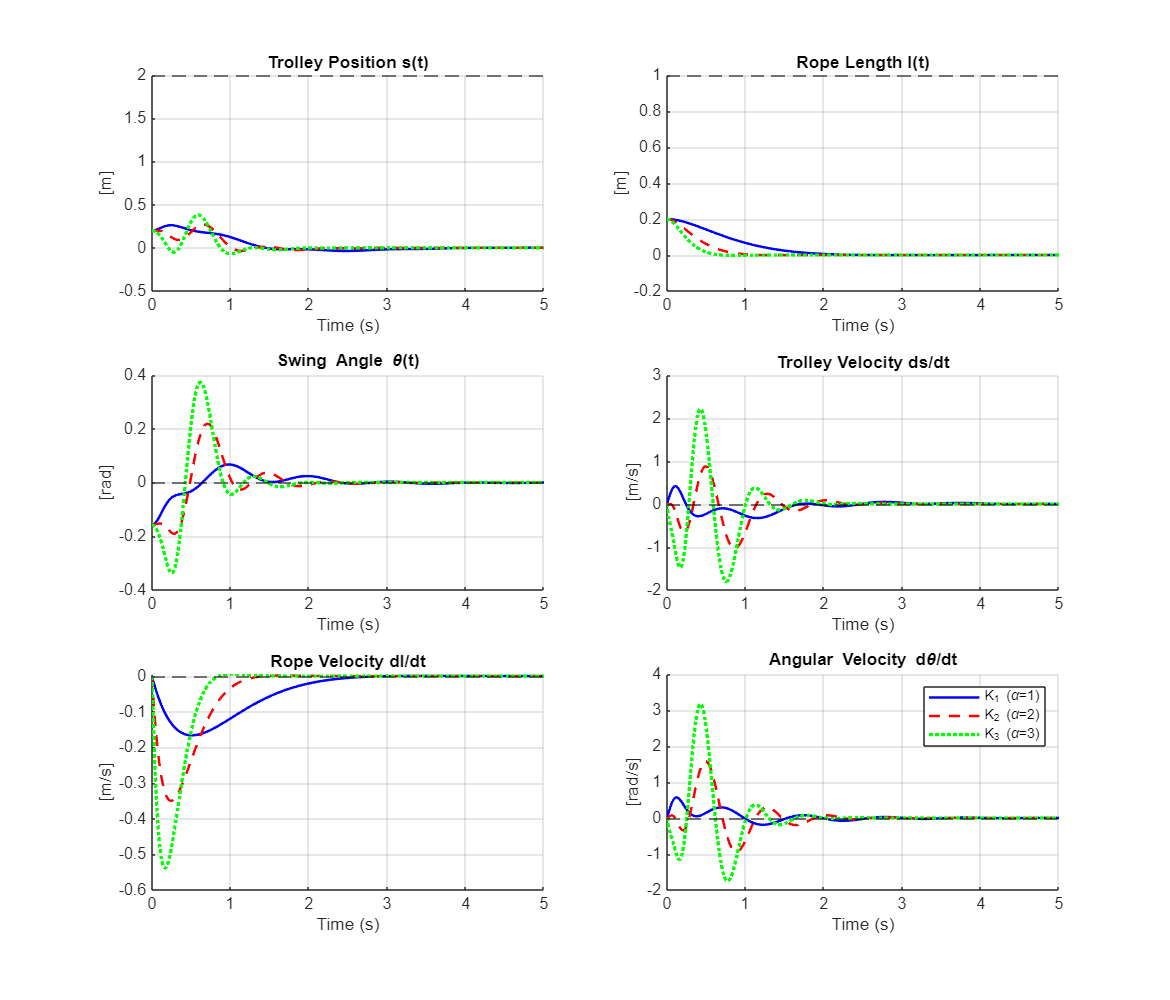

state_titles = {'Trolley Position s(t)', 'Rope Length l(t)', 'Swing Angle \theta(t)', ...
                'Trolley Velocity ds/dt', 'Rope Velocity dl/dt', 'Angular Velocity d\theta/dt'};
state_units = {'[m]', '[m]', '[rad]', '[m/s]', '[m/s]', '[rad/s]'};
figure('Name', 'Linear System State Trajectories', 'Position', [100, 100, 1000, 900]);
for i = 1:6
    subplot(3, 2, i); hold on; grid on;
    plot(results{1}.t, results{1}.x_lin(:,i), 'b-', 'LineWidth', 1.5);
    plot(results{2}.t, results{2}.x_lin(:,i), 'r--', 'LineWidth', 1.5);
    plot(results{3}.t, results{3}.x_lin(:,i), 'g:', 'LineWidth', 2);
    yline(x_eq(i), 'k--');
    title(state_titles{i}); xlabel('Time (s)'); ylabel(state_units{i});
    
end
legend('K_1 (\alpha=1)', 'K_2 (\alpha=2)', 'K_3 (\alpha=3)');

#### Estimated State Trajectories

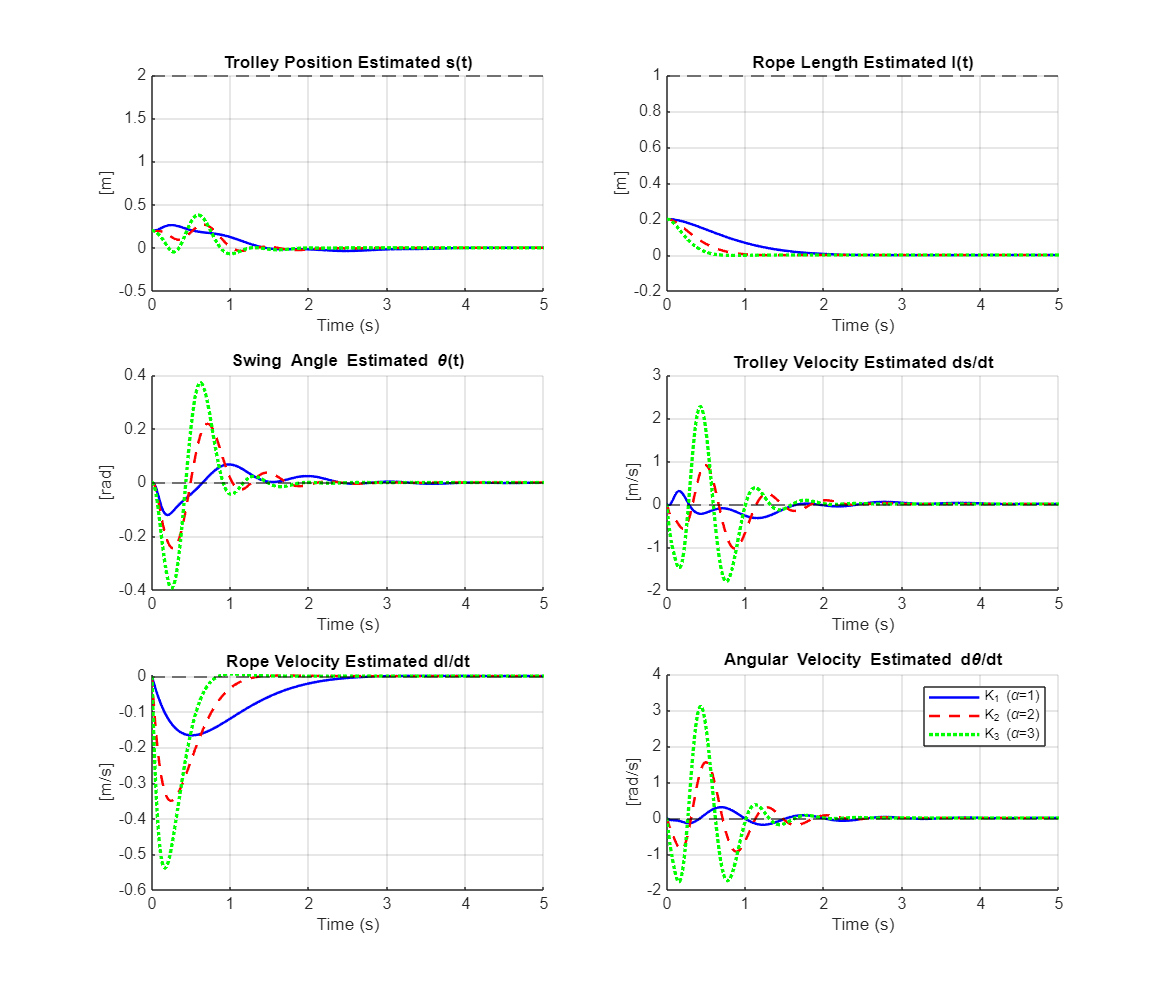

state_titles = {'Trolley Position Estimated s(t)', 'Rope Length Estimated l(t)', 'Swing Angle Estimated \theta(t)', ...
                'Trolley Velocity Estimated ds/dt', 'Rope Velocity Estimated dl/dt', 'Angular Velocity Estimated d\theta/dt'};
state_units = {'[m]', '[m]', '[rad]', '[m/s]', '[m/s]', '[rad/s]'};
figure('Name', 'Linear System State Trajectories', 'Position', [100, 100, 1000, 900]);
for i = 1:6
    subplot(3, 2, i); hold on; grid on;
    plot(results{1}.t, results{1}.x_lin_estimated(:,i), 'b-', 'LineWidth', 1.5);
    plot(results{2}.t, results{2}.x_lin_estimated(:,i), 'r--', 'LineWidth', 1.5);
    plot(results{3}.t, results{3}.x_lin_estimated(:,i), 'g:', 'LineWidth', 2);
    yline(x_eq(i), 'k--');
    title(state_titles{i}); xlabel('Time (s)'); ylabel(state_units{i});
    
end
legend('K_1 (\alpha=1)', 'K_2 (\alpha=2)', 'K_3 (\alpha=3)');

#### Control Input Forces

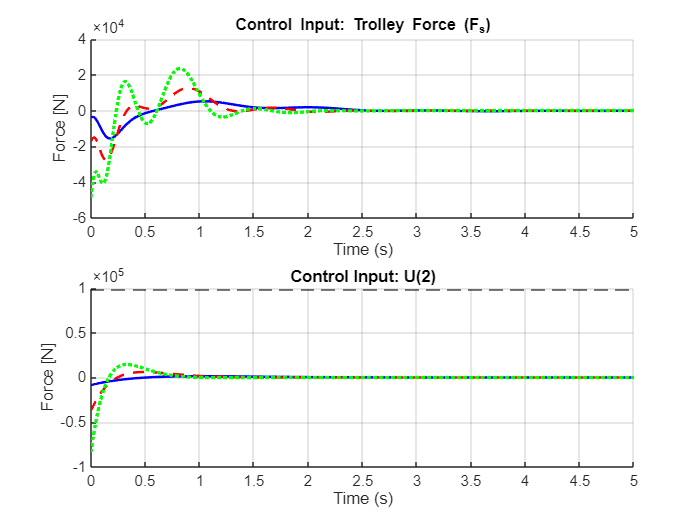

figure('Name', 'Control Inputs');
subplot(2, 1, 1); hold on; grid on;
plot(results{1}.t, results{1}.u_Fs, 'b-', 'LineWidth', 1.5);
plot(results{2}.t, results{2}.u_Fs, 'r--', 'LineWidth', 1.5);
plot(results{3}.t, results{3}.u_Fs, 'g:', 'LineWidth', 2);
title('Control Input: Trolley Force (F_s)'); xlabel('Time (s)'); ylabel('Force [N]');

subplot(2, 1, 2); hold on; grid on;
plot(results{1}.t, results{1}.u_Fl, 'b-', 'LineWidth', 1.5);
plot(results{2}.t, results{2}.u_Fl, 'r--', 'LineWidth', 1.5);
plot(results{3}.t, results{3}.u_Fl, 'g:', 'LineWidth', 2);
yline(vm * vg, 'k--', 'Label', 'Gravity Force');
title('Control Input: U(2)'); xlabel('Time (s)'); ylabel('Force [N]');

# Question 4

 Simulate the nonlinear system

We now simulate the original nonlinear model of the crane under each K (K1, K2, K3). The goal is to check which controller is more robust in practice. We compute the control input using the estimated state: u = Ki * x̂

The observer is assumed ideal (i.e., x̂ = x) to isolate controller performance.

x0_lin = x0;
x0_nonlin = x0_lin + x_eq;


% Simulation for each controller
results = {};
for i = 1:length(K_list)
    fprintf('Simulating with controller K_%d (α = %d)...\n', i, i);
    K = K_list{i};
    ode_fun = @(t, x) nonlinear_dynamics(t, x, K, vM, vm, vc, vg, x_eq);
    [t, x_nonlin] = ode15s(ode_fun, t_span, x0_nonlin);   
    
    results{i}.t = t;
    results{i}.x_nonlin = x_nonlin;
    
    u_Fs = zeros(length(t), 1);
    u_Fl = zeros(length(t), 1);
    for j = 1:length(t)
        x_lin_j = x_nonlin(j,:)' - x_eq;
        u_lin_j = K * x_lin_j;
        u_Fs(j) = u_lin_j(1);
        u_Fl(j) = u_lin_j(2) - vm * vg;  % Isolate Fl
    end
    results{i}.u_Fs = u_Fs;
    results{i}.u_Fl = u_Fl;
end

Simulating with controller K_1 (α = 1)...
Simulating with controller K_2 (α = 2)...
Simulating with controller K_3 (α = 3)...


We now compare the three simulations to choose the best controller for implementation.

#### State Trajectories

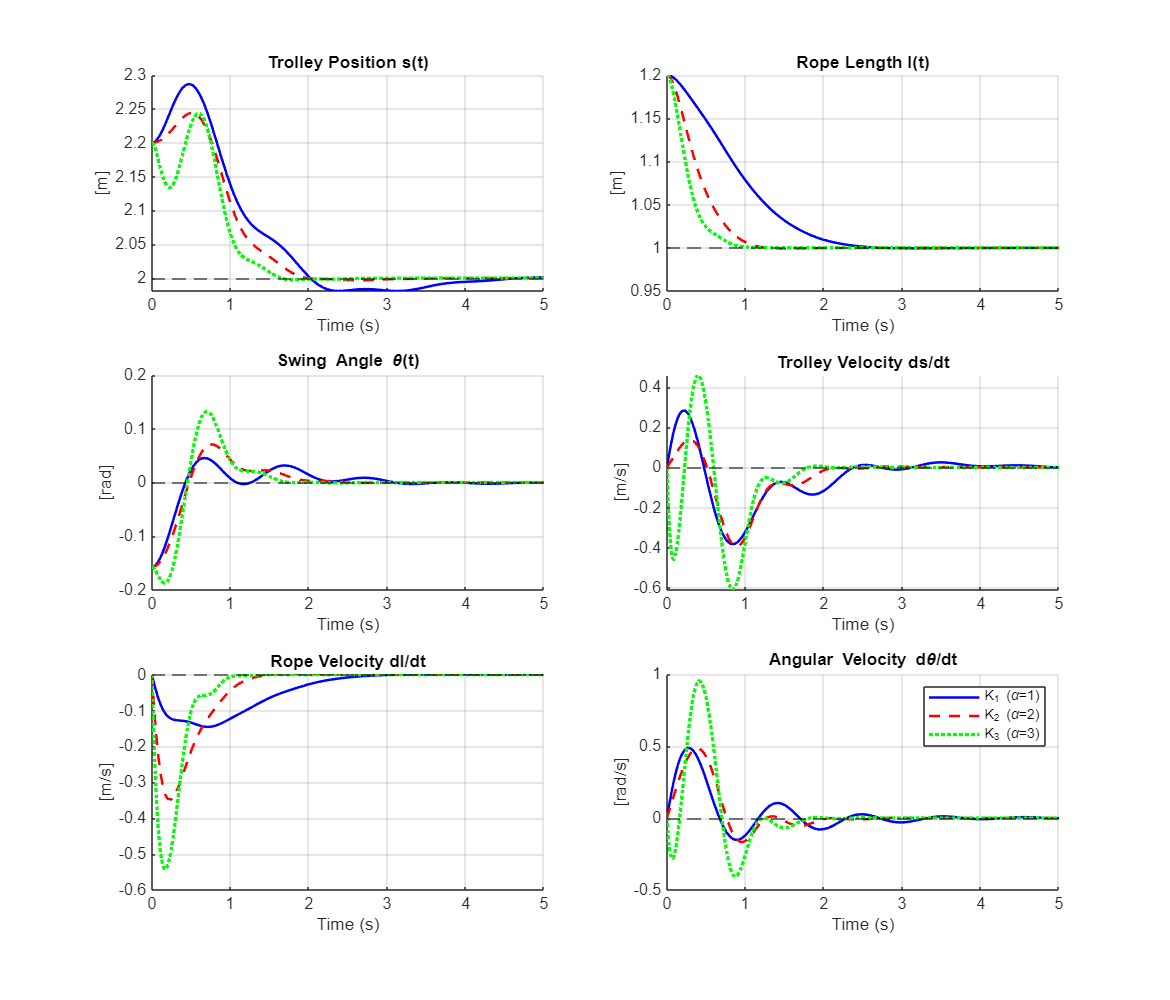

state_titles = {'Trolley Position s(t)', 'Rope Length l(t)', 'Swing Angle \theta(t)', ...
                'Trolley Velocity ds/dt', 'Rope Velocity dl/dt', 'Angular Velocity d\theta/dt'};
state_units = {'[m]', '[m]', '[rad]', '[m/s]', '[m/s]', '[rad/s]'};
figure('Name', 'Linear System State Trajectories', 'Position', [100, 100, 1000, 900]);
for i = 1:6
    subplot(3, 2, i); hold on; grid on;
    plot(results{1}.t, results{1}.x_nonlin(:,i), 'b-', 'LineWidth', 1.5);
    plot(results{2}.t, results{2}.x_nonlin(:,i), 'r--', 'LineWidth', 1.5);
    plot(results{3}.t, results{3}.x_nonlin(:,i), 'g:', 'LineWidth', 2);
    yline(x_eq(i), 'k--');
    title(state_titles{i}); xlabel('Time (s)'); ylabel(state_units{i});
    
end
legend('K_1 (\alpha=1)', 'K_2 (\alpha=2)', 'K_3 (\alpha=3)');

#### Control Input Forces

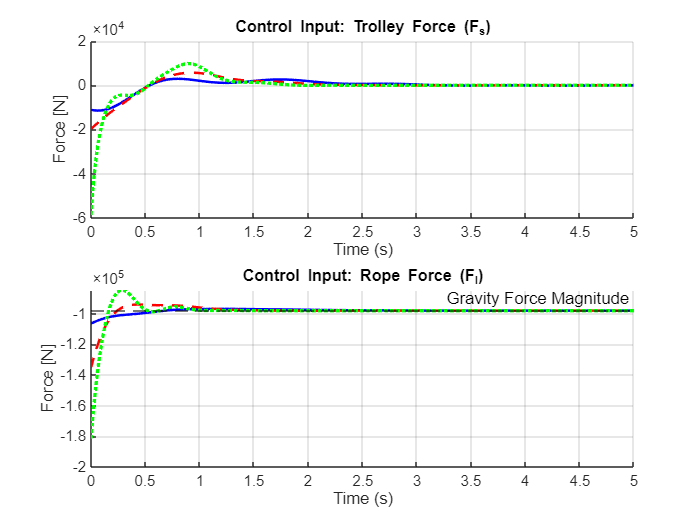

figure('Name', 'Control Inputs');
subplot(2, 1, 1); hold on; grid on;
plot(results{1}.t, results{1}.u_Fs, 'b-', 'LineWidth', 1.5);
plot(results{2}.t, results{2}.u_Fs, 'r--', 'LineWidth', 1.5);
plot(results{3}.t, results{3}.u_Fs, 'g:', 'LineWidth', 2);
title('Control Input: Trolley Force (F_s)'); xlabel('Time (s)'); ylabel('Force [N]');

subplot(2, 1, 2); hold on; grid on;
plot(results{1}.t, results{1}.u_Fl, 'b-', 'LineWidth', 1.5);
plot(results{2}.t, results{2}.u_Fl, 'r--', 'LineWidth', 1.5);
plot(results{3}.t, results{3}.u_Fl, 'g:', 'LineWidth', 2);
yline(-vm * vg, 'k--', 'Label', 'Gravity Force Magnitude');
title('Control Input: Rope Force (F_l)'); xlabel('Time (s)'); ylabel('Force [N]');